# Clasificación Lineal 💋💋💋

clear; close all; clc;

### Importamos los datos de los vinos

Vt = readmatrix('wine/wine.data','FileType','text');

V1 = Vt(1:59,2:end);
V2 = Vt(60:130,2:end);
V3 = Vt(131:end,2:end);

AA = V1;
BB = [V2; V3];

n = 13

n = 13


Q = [  eye(n)    zeros(n,1);
     zeros(1,n)     0
     ];
c = zeros(n+1,1);


F = [-AA -ones(59,1);
      BB ones(119,1)];
d = ones(178,1);
[x, mu, z, iter] = qpintpoint2(Q,F,c,d)

  1 9003.93409570 
  2 5324.19045178 
  3 2428.50691171 
  4 632.75513501 
  5 306.17517963 
  6 102.20721329 
  7 0.52191083 
  8 0.22490991 
  9 0.03546176 
 10 0.01349456 
 11 0.00663089 
 12 0.00329782 
 13 0.00164424 
 14 0.00082073 
 15 0.00040992 
 16 0.00020481 
 17 0.00010236 
 18 0.00005117 
 19 0.00002558 
 20 0.00001279 
 21 0.00000639 


x =    -1.0386
   -0.4059
   -2.3337
    0.2809
    0.0005
   -0.2033
   -0.8243
   -0.5479
    0.1603
    0.1347


mu =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


z =     3.4485
    2.5629
    2.4065
    5.4400
    0.0289
    4.8996
    4.4309
    3.8916
    3.0475
    2.0244


iter = 21

w = x(1:n)

w =    -1.0386
   -0.4059
   -2.3337
    0.2809
    0.0005
   -0.2033
   -0.8243
   -0.5479
    0.1603
    0.1347


beta = x(n+1:end)

beta = 21.8896

min(mu)

ans = 7.5961e-08

min(z)

ans = 1.4675e-07

norm(z)

ans = 34.0796


S1 = AA*w + beta

S1 =    -4.4485
   -3.5629
   -3.4065
   -6.4400
   -1.0289
   -5.8996
   -5.4309
   -4.8916
   -4.0475
   -3.0244


max(S1)

ans = -1.0000

S2 = BB*w + beta

S2 =     4.3921
    2.7204
    4.3278
    2.0104
    2.7731
    3.8122
    1.3183
    1.5348
    3.6185
    1.0000


min(S2)

ans = 1.0000

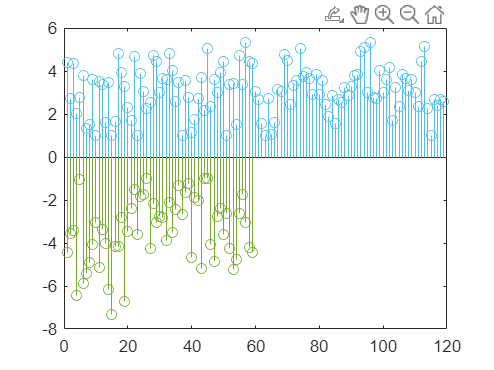


stem(S1)
hold on
stem(S2)